# System Identification (MPC)

## 1. Load + format data

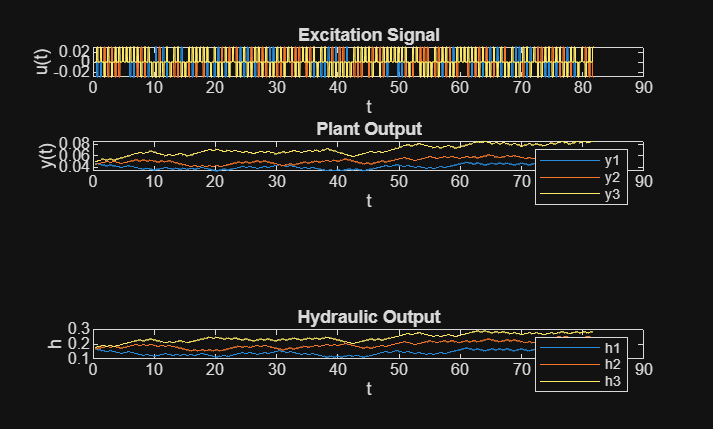

data_path_est = fullfile("data", "noise-free", "IdMPC_est.mat");
data_path_val = fullfile("data", "noise-free", "IdMPC_val.mat");
Ts = 0.02;
load(data_path_est);
% Drop the first sample
startIdx = 20;
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
% y_real = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

figure;
subplot(4, 1, 1);
plot(t, u);
title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
subplot(4, 1, 2);
plot(t, y);
title('Plant Output'); xlabel('t'); ylabel('y(t)');
legend("y1", "y2", "y3");
% subplot(4, 1, 3);
% plot(t, y_real);
% title('Plant Output (Noise-free)'); xlabel('t'); ylabel('y(t)');
% legend("y1", "y2", "y3");
subplot(4, 1, 4);
plot(t, l_hy);
title('Hydraulic Output'); xlabel('t'); ylabel('h');
legend("h1", "h2", "h3");

## 2. Create `iddata` + detrend

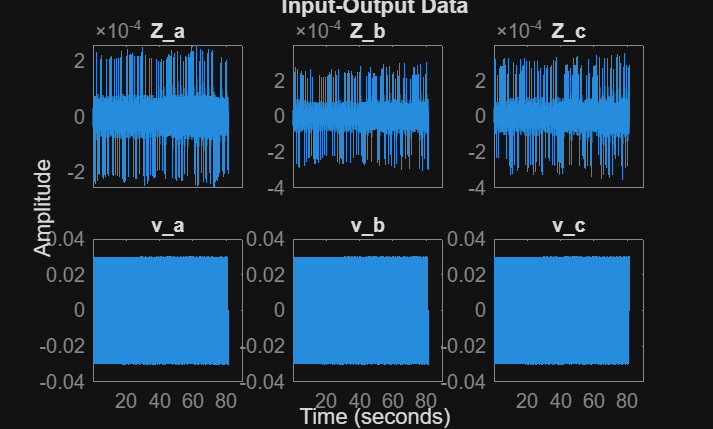

y = diff(y);
u = diff(u);

data = iddata(y, u, Ts, "TimeUnit", "s");
data.InputName = {"v_a", "v_b", "v_c"};
data.OutputName = {"Z_a", "Z_b", "Z_c"};

% remove mean
% data = detrend(data, 0);

figure;
idplot(data);

## 3. Split estimation/validation

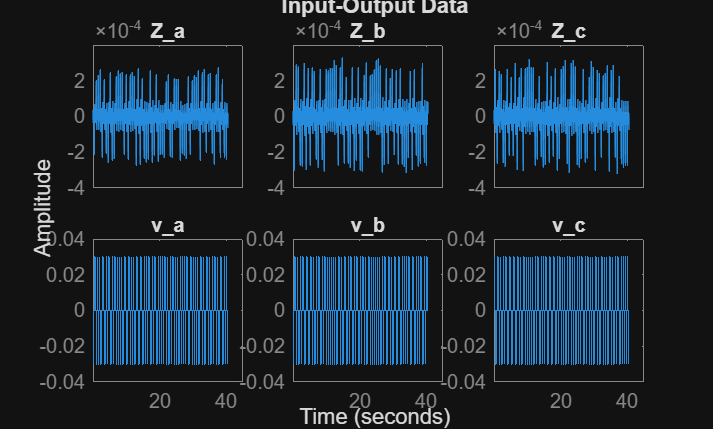

% N = size(data.OutputData, 1);
% Ne = floor(0.7*N);
% 
% data_est = data(1:Ne);
% data_val = data(Ne+1:end);

data_est = data;
load(data_path_val);
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
% y = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

u = diff(u);
y = diff(y);

data_val = iddata(y, u, Ts, "TimeUnit", "s");
data_val.InputName = {"v_a", "v_b", "v_c"};
data_val.OutputName = {"Z_a", "Z_b", "Z_c"};
figure;
idplot(data_val);

## 4. Estimate state-space order by scanning (n4sid -> ssest refine)

orders = 2:15;
% orders = 9;

optN4 = n4sidOptions( ...
    'Focus','simulation', ...
    'N4Weight','CVA');

optSS = ssestOptions( ...
    'Focus','simulation', ...
    'EnforceStability', false);   % allow poles near z=1

optCO = compareOptions("InitialCondition", "estimate");

bestFit = -Inf;
bestSys = [];

for nx = orders
    sys0 = n4sid(data_est, nx, optN4);      % subspace initial model
    sys  = ssest(data_est, sys0, optSS);    % PEM refinement (usually improves fit)
    
    [~, fit] = compare(data_val, sys, optCO);      % fit is 1×3 (%)
    meanFit = mean(fit);

    fprintf('nx=%d, fit=[%.1f %.1f %.1f], mean=%.1f\n', nx, fit, meanFit);

    if meanFit > bestFit
        bestFit = meanFit;
        bestSys = sys;
    end
end

nx=2, fit=[-1.0 12.4 24.7], mean=12.1
nx=3, fit=[8.4 9.7 10.3], mean=9.5
nx=4, fit=[10.9 47.1 22.8], mean=26.9
nx=5, fit=[14.7 32.7 9.2], mean=18.9
nx=6, fit=[56.3 57.6 56.5], mean=56.8
nx=7, fit=[-4.9 74.7 90.1], mean=53.3
nx=8, fit=[42.6 56.0 87.6], mean=62.1
nx=9, fit=[89.8 90.2 94.6], mean=91.5
nx=10, fit=[90.2 90.1 95.8], mean=92.1
nx=11, fit=[91.2 90.1 96.2], mean=92.5
nx=12, fit=[91.3 90.7 96.3], mean=92.8
nx=13, fit=[91.1 90.7 96.4], mean=92.7
nx=14, fit=[91.3 90.8 96.3], mean=92.8
nx=15, fit=[85.5 78.5 87.8], mean=83.9



bestSys


bestSys =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14
   x1       0.8857      0.3879     -0.0964   -0.001906      -0.003    -0.01598    -0.00723   -0.000226  -0.0002625   0.0006017    0.001462  -0.0008558    0.003658    0.004253
   x2       -0.395      0.7894      0.3294    -0.01288     0.00303    -0.02434   -0.001803    0.001897    0.008492   -0.001236   0.0004213  -0.0005745   -0.003979   -0.006504
   x3     -0.07799     -0.4035    -0.01278     0.04714    -0.01415   0.0003711   -0.002175   -0.003356    0.008668  -0.0002367     0.00274   -0.004369     0.02281     0.03996
   x4      0.01011    0.002584       0.031      0.8714      0.3729     -0.1092   -0.003664   -0.003787    0.009869   0.0006778    0.002683    0.001253     0.0

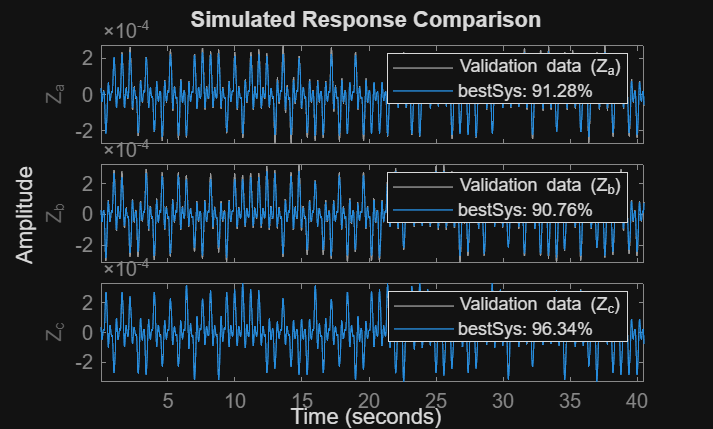

figure;
compare(data_val, bestSys, optCO);

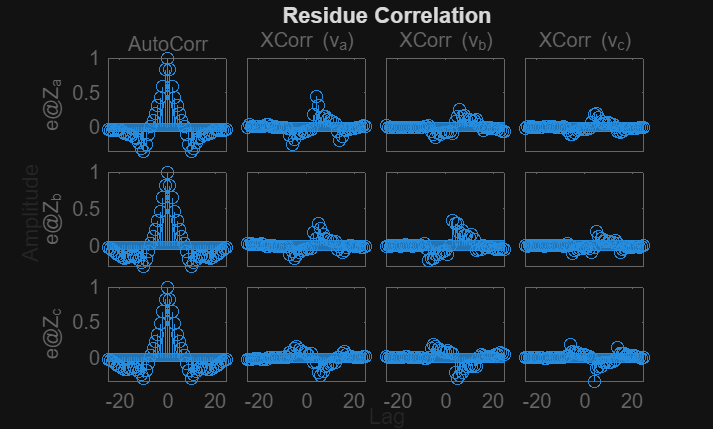

figure;
resid(data_val, bestSys);

eig(bestSys.A)   % expect at least one eigenvalue near 1

ans =    0.0299 + 0.0000i
   0.0803 + 0.0000i
   0.1250 + 0.0000i
   0.8751 + 0.4154i
   0.8751 - 0.4154i
   0.7869 + 0.4391i
   0.7869 - 0.4391i
   0.7870 + 0.4404i
   0.7870 - 0.4404i
   0.7862 + 0.4398i
   0.7862 - 0.4398i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


## 5. Validate the model

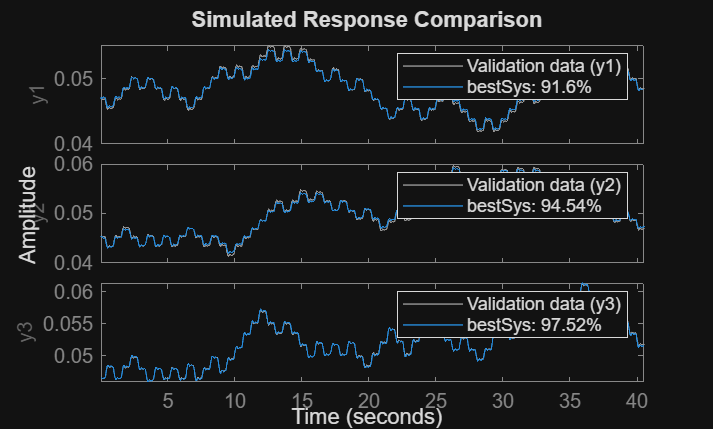

%% --- Convert the incremental model to a standard model ---
[A,B,C,D] = ssdata(bestSys);

nx = size(A,1);
ny = size(C,1);
nu = size(B,2);

Iy = eye(ny);
Iu = eye(nu);

Aaug = [ A,          zeros(nx,ny),   -B;
         C,          Iy,             -D;
         zeros(nu,nx), zeros(nu,ny), zeros(nu,nu) ];

Baug = [ B;
         D;
         Iu ];

Caug = [ C, Iy, -D ];
Daug = D;

bestSys = ss(Aaug, Baug, Caug, Daug, Ts);   % input=u, output=y

load(data_path_val, "t", "u", "y");
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
% y = y_real(startIdx:end, :);
data_val = iddata(y, u, Ts, "TimeUnit", "s");
figure;
compare(data_val, bestSys, optCO);



% %% --- Kalman state estimator for incremental model (du -> dy) ---
% % data_val: iddata with Output=dy, Input=du
% du = data_val.InputData;     % [N x nu]
% dy = data_val.OutputData;    % [N x ny]
% N  = size(dy,1);
% 
% % Extract state-space matrices
% [A,B,C,D] = ssdata(bestSys);
% 
% % Get Kalman gain from identified innovation model (idss)
% if ~isempty(bestSys.K)
%     K = bestSys.K;
% else
%     error("bestSys has no Kalman gain K. Make sure bestSys is an idss (innovation form).");
% end
% 
% nx = size(A,1);
% ny = size(C,1);
% 
% % Initial state (required): x0 = 0
% xhat = zeros(nx,1);
% 
% % Allocate
% dy_hat = zeros(N, ny);
% 
% % Kalman filter recursion (innovation form):
% %   e(k)     = dy(k) - (C x(k) + D du(k))
% %   x(k+1)   = A x(k) + B du(k) + K e(k)
% for k = 1:N
%     uk = du(k,:).';                 % [nu x 1]
%     yk = dy(k,:).';                 % [ny x 1]
% 
%     y_pred = C*xhat + D*uk;         % dy one-step-ahead prediction
%     dy_hat(k,:) = y_pred.';         % store
% 
%     e = yk - y_pred;                % innovation
%     xhat = A*xhat + B*uk + K*e;     % state update
% end
% 
% %% --- Reconstruct y_hat using measured initial y as anchor ---
% data_path = fullfile("data", "IdMPC_val.mat");
% load(data_path, "y_real");               % y is the ORIGINAL (non-incremental) output
% 
% y0 = y_real(startIdx, :);
% y_hat = y0 + cumsum(dy_hat, 1);
% 
% % Safer indexing (avoid length mismatch)
% idx = startIdx + (1:N);             % corresponds to y(k) for k=startIdx+1...startIdx+N
% 
% %% --- Plot y vs y_hat ---
% figure;
% for i = 1:3
%     subplot(3,1,i);
%     plot(y_real(idx, i)); hold on;
%     plot(y_hat(:, i)); hold off;
%     grid on;
%     legend("y", "y_hat");
% end

## 6. MPC implementation

plant = ss(bestSys);
max(abs(eig(plant.A)))  % No eigenvalue noticeably > 1

ans = 1.0000


p = 40;  % prediction horizon
m = 10;  % control horizon

mpcobj = mpc(plant, Ts, p, m);  % create the MPC object

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


setname(mpcobj, "input", 1, "v_a");
setname(mpcobj, "input", 2, "v_b");
setname(mpcobj, "input", 3, "v_c");
setname(mpcobj, "output", 1, "Z_a");
setname(mpcobj, "output", 2, "Z_b");
setname(mpcobj, "output", 3, "Z_c");

% Put in constraints
v_max = 0.1579; v_min = -0.3612;  % speed range of electrodes
for i = 1 : 3
    mpcobj.MV(i).Min = v_min;
    mpcobj.MV(i).Max = v_max;
end

mpcobj.Weights.OutputVariables = [1 1 1];              % track impedance
mpcobj.Weights.ManipulatedVariables = [0 0 0];         % usually small/zero
mpcobj.Weights.ManipulatedVariablesRate = [0.1 0.1 0.1]; % smooth velocity moves
mpcobj.Weights.ECR = 1e5;                               % penalty for constraint softening

% % Create the output disturbance model
% integrator = tf(1, [1 -0.95], Ts);
% outdist = blkdiag(integrator, integrator, integrator);
% setoutdist(mpcobj, 'model', outdist);
% 
% xc = mpcstate(mpcobj);
% [numel(xc.Plant) numel(xc.Disturbance) numel(xc.Noise)]

mpcobj

 
MPC object (created on 28-Feb-2026 20:18:21):
---------------------------------------------
Sampling time:      0.02 (seconds)
Prediction Horizon: 40
Control Horizon:    10

Plant Model:        
                                      --------------
      3  manipulated variable(s)   -->| 20 states  |
                                      |            |-->  3 measured output(s)
      0  measured disturbance(s)   -->|  3 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  3 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: [0 0 0]
    ManipulatedVariablesRate: [0.1000 0.1000 0.1000]
             OutputVariables: [1 1 1]
                         ECR: 100000

State Estimation:  Def